# 2D Hughes model

clear; clc; close all;

## Domain & grid


Nx = 80; Ny = 80;
Lx = 20; Ly = 20;
dx = Lx/Nx; dy = Ly/Ny;
[x, y] = meshgrid(linspace(dx/2,Lx-dx/2,Nx), linspace(dy/2,Ly-dy/2,Ny));


## Parameters

Vmax = 1.5;
rho_max = 1.0;
CFL = 0.4;

## Initial density: Gaussian blob in center

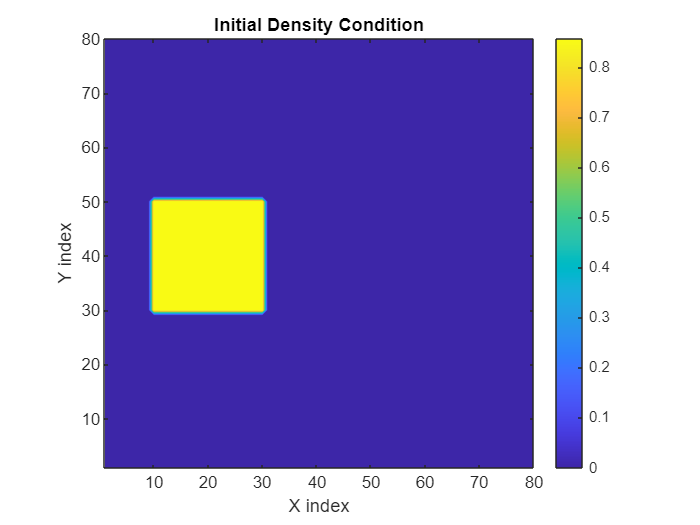

rho = zeros(Nx,Ny);% Assuming rho is your initial density matrix
rho(30:50,10:30) = 0.9;
rho = min(rho,rho_max);

figure;
contourf(rho, 20, 'LineColor', 'none');
colorbar;
axis equal tight;
xlabel('X index');
ylabel('Y index');
title('Initial Density Condition');

## Exit mask: only middle section of right boundary

% This line will make everything false. 
exit_mask = false(Ny,Nx);
% Here we define the limit of the y cordinates were we want to have the
% outflow, and this will be assigned true.
% Lets say I want to just open the right corner for the exit.
exit_mask(:,Nx) = true;     % Right boundary

## Create obstacle mask

The obstacle here is just a square region in the middle of the domain.

obstacle_mask = false(Ny, Nx);
%{
% Middle segment of the wall
y1 = 30; y2 = 70;
x1 = 60; x2 = 70;
obstacle_mask(y1:y2, x1:x2) = true;
%}

## Time loop

**The eikonal Equation**: This is the solved in the loop using the function "fast_sweeping_2d", and this will essentially calculate the new values of phi, using the old values of rho (in the form of speed, f).

Then the loop actually calculates the velocity vector using the valkues of new phi, since that is needed to come up with the direction cosine of the vectors.

And then using the newly created vector, using the newly created phi, we proceed to calculate the new values of rho.

**New Rho Values**: Now to calculate the new values of rho, we use the old values of rho, along with the new values of phi, in the form of newly found velocity, which has newly made phi incorporated in them.

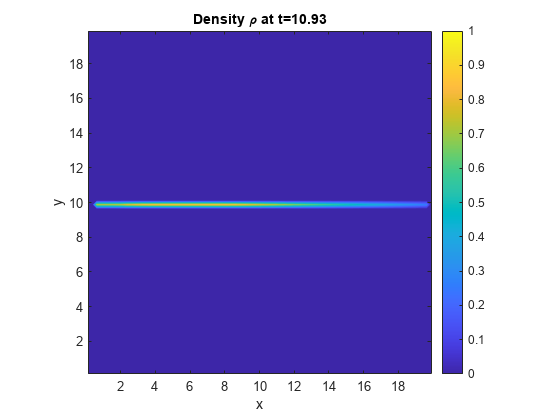

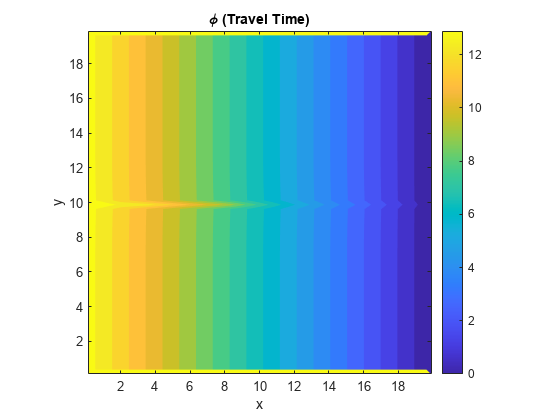

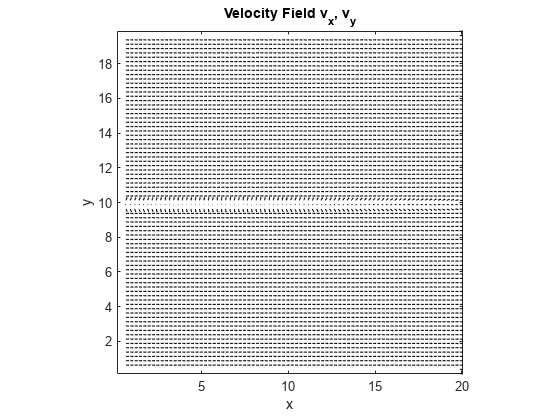

Tfinal = 50;
t = 0;

while t < Tfinal
    % Step 1: Speed field
    f = Vmax*(1 - rho/rho_max);
    f(f<1e-6) = 1e-6;

    % Step 2: Solve eikonal equation
    phi = fast_sweeping_2d(1./f, dx, dy, exit_mask, obstacle_mask);

    % Step 3: Direction field
    [phix, phiy] = gradient(phi, dx, dy);
    grad_mag = sqrt(phix.^2 + phiy.^2) + 1e-12;
    dirx = -phix ./ grad_mag;
    diry = -phiy ./ grad_mag;

    % Step 4: Velocity field
    vx = f .* dirx;
    vy = f .* diry;

    % Step 5: Boundary conditions
    vx(:,1)   = 0; % Left wall
    vx(:,end) = Vmax .* exit_mask(:,end); % Exit velocity
    vy(1,:)   = 0; % Bottom wall
    vy(end,:) = 0; % Top wall

    % Step 6: Time step
    maxspeed = max(max(sqrt(vx.^2 + vy.^2)));
    dt = CFL * min(dx,dy) / maxspeed;
    if t+dt > Tfinal, dt = Tfinal-t; end

    % Step 7: Update rho
    rho = upwind_update_2d(rho, vx, vy, dx, dy, dt, exit_mask, obstacle_mask);

    % Step 8: Advance time
    t = t + dt;

    % Step 9: Plot ONLY density
    if mod(round(t/dt),2) == 0

        figure(1);
        contourf(x, y, rho, 20, 'LineColor', 'none');
        colorbar; caxis([0 rho_max]);
        title(sprintf('Density \\rho at t=%.2f', t));
        xlabel('x'); ylabel('y'); axis equal tight;

         % Figure 2: Potential (phi)
        figure(2);
        contourf(x, y, phi, 20, 'LineColor', 'none');
        colorbar;
        title('\phi (Travel Time)');
        xlabel('x'); ylabel('y'); axis equal tight;
    
        % Figure 3: Velocity field
        figure(3);
        quiver(x, y, vx, vy, 0.5, 'k');
        title('Velocity Field \bf{v_x, v_y}');
        xlabel('x'); ylabel('y');
        axis equal tight;

        drawnow;
    end
end

## --- Helper functions : fast_sweeping_2d ---

This function uses the fast sweeping method for solving the **eikonal equation**.

function phi = fast_sweeping_2d(invf, dx, dy, exit_mask,obstacle_mask)
    Ny = size(invf,1); Nx = size(invf,2);
    phi = inf(Ny,Nx);
    phi(exit_mask) = 0;
    for sweep=1:200
        for i=2:Ny-1
            for j=2:Nx-1
                if exit_mask(i,j) || obstacle_mask(i,j)
                continue; % Skip exits and obstacles
                end

                ax = min(phi(i,j-1), phi(i,j+1));
                ay = min(phi(i-1,j), phi(i+1,j));
                tmp = sort([ax, ay]);
                if abs(tmp(1)-tmp(2)) >= invf(i,j)*dx
                    phi(i,j) = tmp(1) + invf(i,j)*dx;
                else
                    phi(i,j) = (tmp(1)+tmp(2) + sqrt(2*(invf(i,j)*dx)^2 - (tmp(1)-tmp(2))^2))/2;
                end
            end
        end
    end
end

## --- Helper functions : upwind_update_2d ---%

function rho_new = upwind_update_2d(rho, vx, vy, dx, dy, dt, exit_mask, obstacle_mask)
    [Ny, Nx] = size(rho);
    % Preallocate flux arrays
    flux_xp = zeros(Ny, Nx);
    flux_xm = zeros(Ny, Nx);
    flux_yp = zeros(Ny, Nx);
    flux_ym = zeros(Ny, Nx);
    % Loop in correct order
    for j = 2:Ny-1
        for i = 2:Nx-1
            if exit_mask(j,i) || obstacle_mask(j,i)
                continue; % Skip exit and obstacles
            end
            flux_xp(j,i) = max(vx(j,i),0)*rho(j,i) + min(vx(j,i),0)*rho(j,i+1);
            flux_xm(j,i) = max(vx(j,i),0)*rho(j,i-1) + min(vx(j,i),0)*rho(j,i);
            flux_yp(j,i) = max(vy(j,i),0)*rho(j,i) + min(vy(j,i),0)*rho(j-1,i);
            flux_ym(j,i) = max(vy(j,i),0)*rho(j+1,i) + min(vy(j,i),0)*rho(j,i);
        end
    end
    % Update rho outside the loops
    rho_new = rho - (dt/dx)*(flux_xp - flux_xm) - (dt/dy)*(flux_yp - flux_ym);
    % Clamp density
    rho_new = max(0, min(1.0, rho_new));
end
 




















